Filename: Analysis.mlx

Author Name: Vikram Krishna

Author Email: vkrishna@hmc.edu

Date: January 26, 2024

% logreader.m
% Use this script to read data from your micro SD card

clear;
%clf;

filenum = '016'; % file number for the data you want to read
infofile = strcat('data/inf', filenum, '.TXT');
datafile = strcat('data/log', filenum, '.BIN');

## map from datatype to length in bytes

dataSizes.('float') = 4;
dataSizes.('ulong') = 4;
dataSizes.('int') = 4;
dataSizes.('int32') = 4;
dataSizes.('uint8') = 1;
dataSizes.('uint16') = 2;
dataSizes.('char') = 1;
dataSizes.('bool') = 1;

## read from info file to get log file structure

fileID = fopen(infofile);
items = textscan(fileID,'%s','Delimiter',',','EndOfLine','\r\n');
fclose(fileID);
[ncols,~] = size(items{1});
ncols = ncols/2;
varNames = items{1}(1:ncols)';
varTypes = items{1}(ncols+1:end)';
varLengths = zeros(size(varTypes));
colLength = 256;
for i = 1:numel(varTypes)
    varLengths(i) = dataSizes.(varTypes{i});
end
R = cell(1,numel(varNames));

## read column-by-column from datafile

fid = fopen(datafile,'rb');
for i=1:numel(varTypes)
    %# seek to the first field of the first record
    fseek(fid, sum(varLengths(1:i-1)), 'bof');
    
    %# % read column with specified format, skipping required number of bytes
    R{i} = fread(fid, Inf, ['*' varTypes{i}], colLength-varLengths(i));
    eval(strcat(varNames{i},'=','R{',num2str(i),'};'));
end
fclose(fid);

% Crop the data to when  the robot was running
startTick = find(motorB < 0);
startTick = startTick(1);
endTick = find(motorB > 0);
endTick = endTick(length(endTick));
endTick = int64(startTick + endTick)/2

endTick = int64
797

accelX = accelX(startTick:endTick);
accelY = accelY(startTick:endTick);
accelZ = accelZ(startTick:endTick);

% Convert acceleration  from  teensy units to m/s^2
accelX = accelX .* 0.0100951891;
accelY = accelY .* 0.0100951891;
accelZ = accelZ .* 0.0100951891;

## Plot your data here

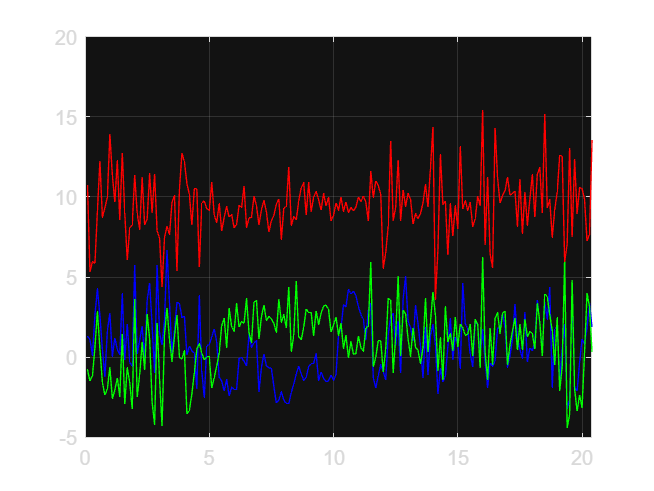

pltX = plot((1:size(accelX))./10, accelX, "Color", "Blue");
hold on
pltY = plot((1:size(accelX))./10, accelY, "Color", "Green");
pltZ = plot((1:size(accelX))./10, accelZ, "Color", "Red");
ax = gca;
ax.XAxis(1).Limits = [0 length(accelX)/10];
grid on

lgd = legend(["X Accel.", "Y Accel.", "Z Accel."], 'Interpreter', 'latex');

Error using legend
Error setting property 'Color' of class 'Legend':
Invalid RGB triplet. Specify a three-element vector of values between 0 and 1.

lgd.TextColor = [0 0 0];
lgd.EdgeColor = [0 0 0];
chartTitle = "Acceleration Over Time";
xlabel("Time (s)", "Color", [0 0 0], 'Interpreter', 'latex');
ylabel("Acceleration $ \left( m/s^{2} \right)$", 'Interpreter', 'latex', "Color", [0 0 0]);
title(chartTitle, "Color", [0 0 0], 'Interpreter', 'latex');
set(gca, 'Color', [1 1 1])
set(gca, "XColor", [0 0 0])
set(gca, "YColor", [0 0 0])
saveas(gcf, "Acceleration", "jpg")
hold off


endStart = find(motorB < 0);
endStart = endStart(length(endStart))

endStart = 632

endStart - startTick

ans = 38


startEnd = find(motorB > 200);
startEnd = startEnd(1)

startEnd = 693

startEnd - endStart

ans = 61

motorB

motorB = 3987×1 int32 column vector
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


(endStart - startTick) / 10

ans = 3.8000

(startEnd - startTick)/ 10

ans = 9.9000